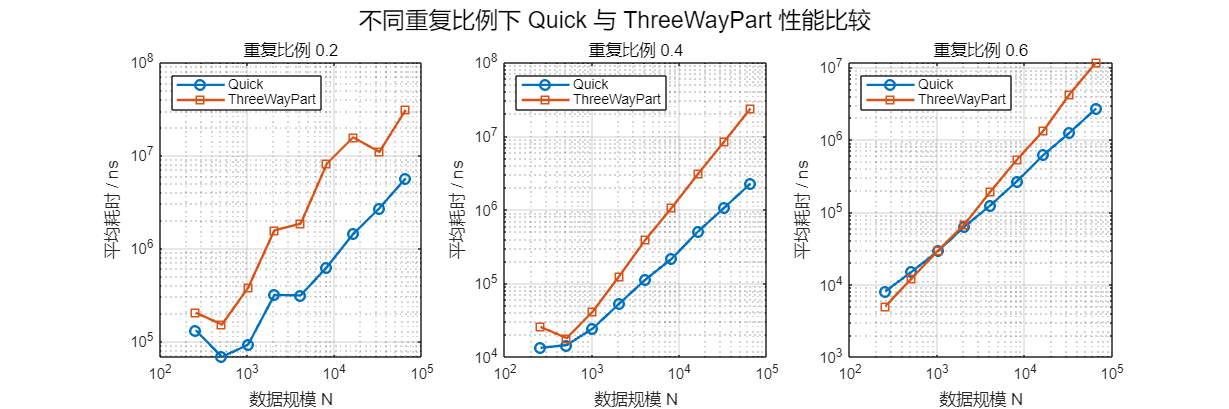

% 数据规模
N = [256 512 1024 2048 4096 8192 16384 32768 65536];

% 数据
Quick_02 = [131980 67800 92060 315120 311500 628420 1427840 2703380 5664200];
Three_02 = [203640 151280 377200 1564140 1839300 8153220 15624480 10918620 30831920];

Quick_04 = [13320 14500 24520 53040 112760 216180 505640 1063900 2269200];
Three_04 = [25660 18020 41800 125200 392340 1063920 3061320 8429840 23645280];

Quick_06 = [8100 15080 29180 63060 125480 269380 616700 1260600 2703420];
Three_06 = [5040 12220 29660 67740 195260 534680 1334760 4285100 11698740];

% 调整 figure 宽度和高度（单位像素）
figure('Position',[100 100 1500 500]);  % 左下角X,Y，宽1500，高500

% 子图 1 - 重复比例 0.2
subplot(1,3,1);
loglog(N, Quick_02, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_02, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.2');
legend('Location','northwest'); grid on;

% 子图 2 - 重复比例 0.4
subplot(1,3,2);
loglog(N, Quick_04, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_04, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.4');
legend('Location','northwest'); grid on;

% 子图 3 - 重复比例 0.6
subplot(1,3,3);
loglog(N, Quick_06, '-o','LineWidth',1.5,'DisplayName','Quick'); hold on;
loglog(N, ThreeWay_06, '-s','LineWidth',1.5,'DisplayName','ThreeWayPart');
xlabel('数据规模 N'); ylabel('平均耗时 / ns'); title('重复比例 0.6');
legend('Location','northwest'); grid on;

sgtitle('不同重复比例下 Quick 与 ThreeWayPart 性能比较');